# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 07-Nov-2022 01:05:43

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 15);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Re", "S", "Ri", "xc", "yc", "Nu", "T", "Pi", "Po", "Nuw_c", "Tw_c", "Piw_c", "Pow_c", "delPdelPo", "delNudelNuo"];
opts.VariableTypes = ["double", "categorical", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Re", "S"], "EmptyFieldRule", "auto");

% Import the data
data = readtable("D:\Matlab Drive\Research\All data merged ready for training.csv", opts)

data = 10920×15 table
    Re    S     Ri      xc     yc       Nu         T         Pi        Po       Nuw_c      Tw_c      Piw_c      Pow_c     delPdelPo    delNudelNuo
    __    _    _____    ___    ___    ______    _______    ______    _______    ______    _______    ______    _______    _________    ___________

    50    0      0.1    0.2    0.2    2.2891    0.14015    4.9081    0.23716    2.2656    0.13955     2.992    0.23141      1.692         1.0104  
    50    0    0.595    0.

## Clear temporary variables

clear opts

**Data Visualization**

Nu

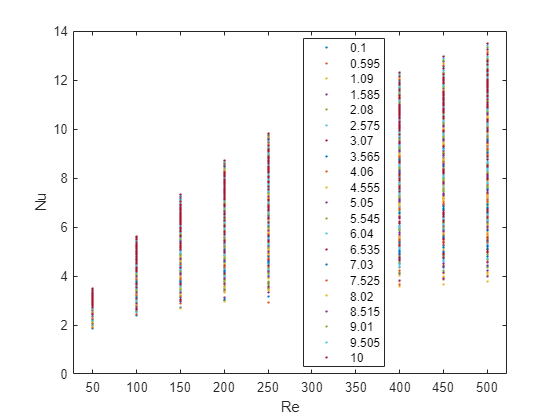

gscatter(data.Re,data.Nu,data.Ri)
xlabel('Re')
ylabel('Nu')

Nubin=1:0.5:14

Nubin =     1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000   12.0000   12.5000   13.0000   13.5000   14.0000


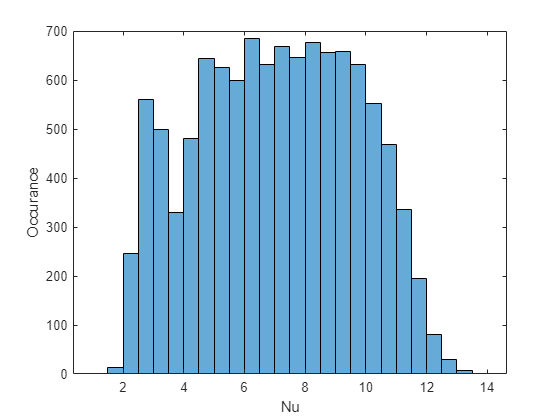

histogram(data.Nu,Nubin)
xlabel('Nu')
ylabel('Occurance')

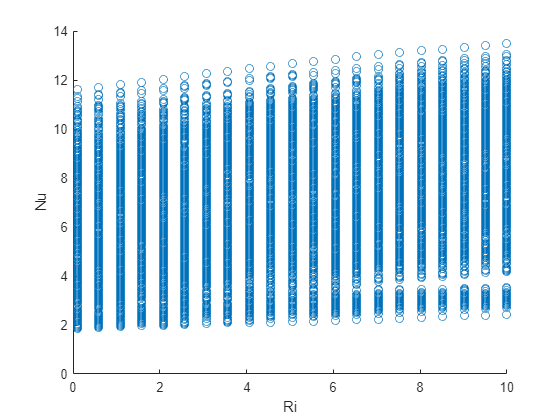

scatter(data.Ri,data.Nu)
xlabel('Ri')
ylabel('Nu')

data2=data(data.Ri==0.1& data.xc==0.2 & data.yc==0.2,:)

data2 = 40×15 table
    Re      S     Ri     xc     yc       Nu         T          Pi         Po       Nuw_c       Tw_c      Piw_c      Pow_c      delPdelPo    delNudelNuo
    ___    ___    ___    ___    ___    ______    ________    ______    ________    ______    ________    ______    ________    _________    ___________

     50    0      0.1    0.2    0.2    2.2891     0.14015    4.9081     0.23716    2.2656     0.13955     2.992     0.23141      1.692         1.0104  
     50    0.

s=gscatter(data2.Re,data2.Nu,data2.S);

s =   4×1 Line array:

  Line    (0)
  Line    (0.5)
  Line    (1)
  Line    (2)


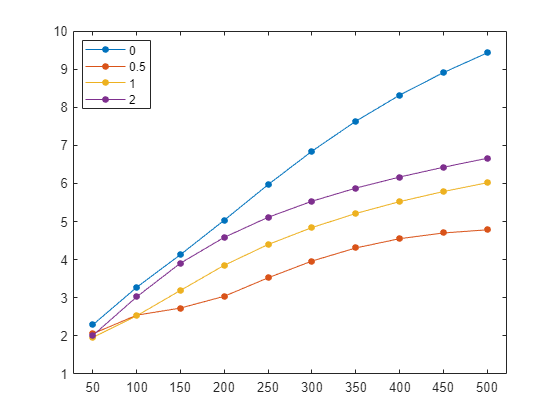

set(s,'linestyle','-')